Ngeom = numel(xd_geom);
alpha_table = linspace(0, 1, Ngeom);   % parámetro geométrico
dx_dalpha = gradient(xd_geom, alpha_table);
dy_dalpha = gradient(yd_geom, alpha_table);
L = 0;
for i = 1:Ngeom-1
    dx = xd_geom(i+1) - xd_geom(i);
    dy = yd_geom(i+1) - yd_geom(i);
    ds = sqrt(dx^2 + dy^2);
    L  = L + ds;
end
fprintf('Arc length L = %.4f m\n', L);

Arc length L = 0.8775 m



tfinal = 15;
c = L / tfinal;
fprintf('Average speed c = %.4f m/s\n', c);

Average speed c = 0.0585 m/s


if c > 0.25
    warning('Average speed c > 0.25 m/s. Ajusta el scale o tfinal.');
end

g = @(t, T, ta) (T/(T-ta))*((t < ta) .* (t / ta) + ...
                            (t >= ta & t <= (T - ta)) .* 1 + ...
                            (t > (T - ta)) .* ((T - t) / ta));

dt = 0.002;
t  = 0:dt:tfinal;
ta = 0.2 * tfinal;
T_path = 1;              % ahora el período geométrico es 1 (α de 0 a 1)

alpha = zeros(size(t));  % alpha(0) = 0


for i = 1:length(t)-1
    % derivada de p_d respecto a alpha usando interpolación
    xdot = interp1(alpha_table, dx_dalpha, alpha(i), 'linear', 'extrap');
    ydot = interp1(alpha_table, dy_dalpha, alpha(i), 'linear', 'extrap');

    s_geom = sqrt(xdot^2 + ydot^2);
    s_geom = max(s_geom, 1e-6);

    v_des   = c * g(t(i), tfinal, ta);
    alpha_dot = v_des / s_geom;

    alpha(i+1) = alpha(i) + alpha_dot * dt;
end

% Normalizar para que alpha(tfinal) llegue exactamente a T_path = 1
alpha = alpha * (T_path / alpha(end));


x_traj = interp1(alpha_table, xd_geom, alpha, 'linear', 'extrap');
y_traj = interp1(alpha_table, yd_geom, alpha, 'linear', 'extrap');

fprintf('real start: (%.3f, %.3f)\n', x_traj(1), y_traj(1));

real start: (0.067, -0.018)


fprintf('real final: (%.3f, %.3f)\n', x_traj(end), y_traj(end));

real final: (0.067, -0.018)


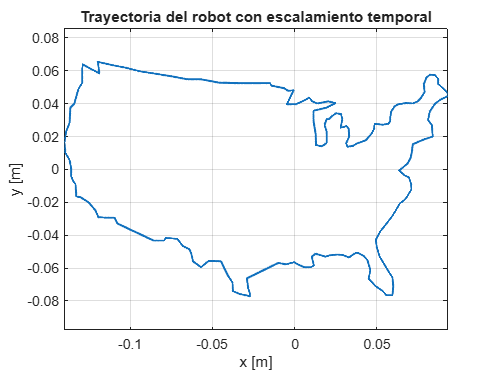


figure;
plot(x_traj, y_traj, 'LineWidth', 1.5); axis equal; grid on;
xlabel('x [m]'); ylabel('y [m]');
title('Trayectoria del robot con escalamiento temporal');


N = length(t);               % mismo N que en Step 1
Tsd = zeros(4,4,N);
for i = 1:N
    pd = [x_traj(i); y_traj(i); 0];
    Rd = eye(3);
    Td = [Rd, pd;
          0 0 0 1];
    Tsd(:,:,i) = T0 * Td;
end

Unrecognized function or variable 'T0'.